# ディープラーニングを使用した人間の活動の分類

これは教師あり学習の例です。 

人間の活動を計測したセンサーデータには、歩く(Walking)、座る(Sitting)、横になる(Laying)、立つ(Standing)、階段を上る(Walking Upstairs)、階段を降りる(Walking Downstairs)という 6 つの異なる活動を行っているときに、人が装着しているスマートフォンから取得したセンサーの観測値が含まれています。 

この例のゴールは、センサー測定に基づいて活動の種類を自動的に識別できるモデルを構築することです。 **この教師あり学習の例では、ラベル付きデータと ****生の****データを操作します。 **

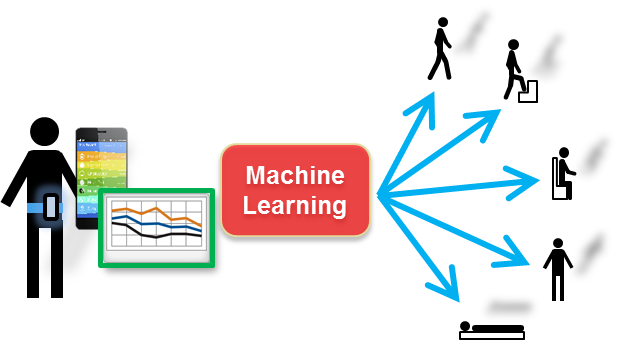

clear;

## データの前処理

前の演習では、元のデータを改変し、特徴量を計算しました。 

生のトレーニング データ セットとテスト データ セット (それぞれ `rawDataTrain` と `rawDataTest`) を再度読み込み、各セットのテーブルを作成しましょう。 

load('rawSensorData_train.mat')
rawDataTrain = table(...
     total_acc_x, total_acc_y, total_acc_z, ...
     body_gyro_x, body_gyro_y, body_gyro_z);

load('rawSensorData_test.mat')
rawDataTest = table(...
    total_acc_x, total_acc_y, total_acc_z, ...
    body_gyro_x, body_gyro_y, body_gyro_z);

両方の変数は同じ方法で構成されています。列は個々のセンサーの種類を表し、行は活動の種類を表します。 

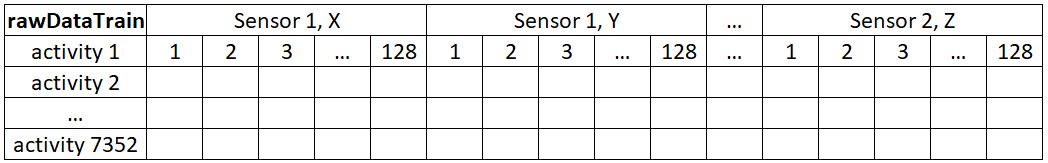

ディープラーニングは生データで良好なパフォーマンスを発揮することが多いため、特徴量の抽出は不要です。ただし、多くの場合、データを「整理」(または「再構築」) すると非常に有益です。このため、個々の活動のデータをセンサー別に整理します。つまり、すべてのセンサーを各時間フレームにグループ化します (たとえば、2.5 秒のフレーム (= 128 の測定) ごとに 6 つのセンサーすべてを含める必要があります)。結果は多次元配列で、各次元にはその特定の時間フレーム (活動) のデータが含まれます。そのため、* "Additional Files" * にあるヘルパー関数 (`groupByActivity`) を使用します。 

numSig_train = size(rawDataTrain,1);
numSig_test = size(rawDataTest,1);

[train_groups, test_groups] = groupByActivity(rawDataTrain, numSig_train, ...
rawDataTest, numSig_test);

train_groups = pagetranspose(train_groups);
test_groups = pagetranspose(test_groups);

ここで、センサーは配列内の各次元の行であるため、各次元 (アクティビティを表す) には 6 つの行があります。 

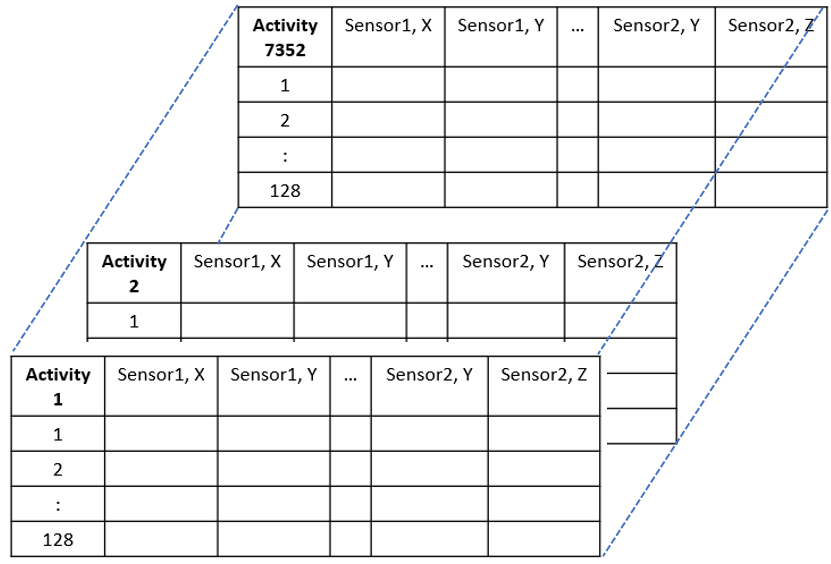

disp(train_groups(:,:,1))

ニューラルネットワークの設計とトレーニングには、ディープ ネットワーク デザイナー アプリを使用します。アプリでは、入力データが [データストア](https://uk.mathworks.com/help/matlab/datastore.html) から取得される必要があります。これは、メモリに収まらないほど大きいデータのコレクションを格納するリポジトリです。さまざまな [データストアの種類](https://uk.mathworks.com/help/matlab/import_export/select-datastore-for-file-format-or-application.html) があり、この場合は [arrayDatastore](https://uk.mathworks.com/help/matlab/ref/matlab.io.datastore.arraydatastore.html) を使用します。 

トレーニング データは、異なるデータ型で構成されています ( `train_groups` は double型、`trainActivity` はcategorical型)。2 つのデータストアを作成して結合してみましょう。 

inDS_train = arrayDatastore(train_groups, IterationDimension=3, OutputType="cell");
outDS_train = arrayDatastore(trainActivity, IterationDimension=1, OutputType="cell");
fullDS_train = combine(inDS_train, outDS_train);

 `testActivity`変数は使用しないため、テスト データ用に 1 つのデータストアのみを作成します。

fullDS_test = arrayDatastore(test_groups, IterationDimension=3, OutputType="cell");

## モデルをトレーニングする

LSTM (Long Short-Term Memory) ネットワークは、シーケンスデータのタイムステップ間の長期的な依存関係を学習できます。この例では、双方向 LSTM レイヤー [`bilstmLayer`](https://uk.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.bilstmlayer.html) を使用します。これは、シーケンスを順方向と逆方向の両方で調べるためです。 

**ディープ ネットワーク デザイナーを使用して LSTM ネットワークを作成する **

 [ディープ ネットワーク デザイナー](https://www.mathworks.com/help/deeplearning/ug/build-networks-with-deep-network-designer.html) (DND) は、ニューラルネットワークを設計およびトレーニングするため使えるグラフィカルインターフェイスです。 

DND アプリを開くには、[アプリ] タブに移動し、[機械学習および深層学習] の下の [ ] アイコンをクリックします。 または、コマンドラインからアプリを開くこともできます 

**ステップ 1: ネットワーク アーキテクチャの選択 **

DND を開いたら、[空のネットワーク] を選択します。 

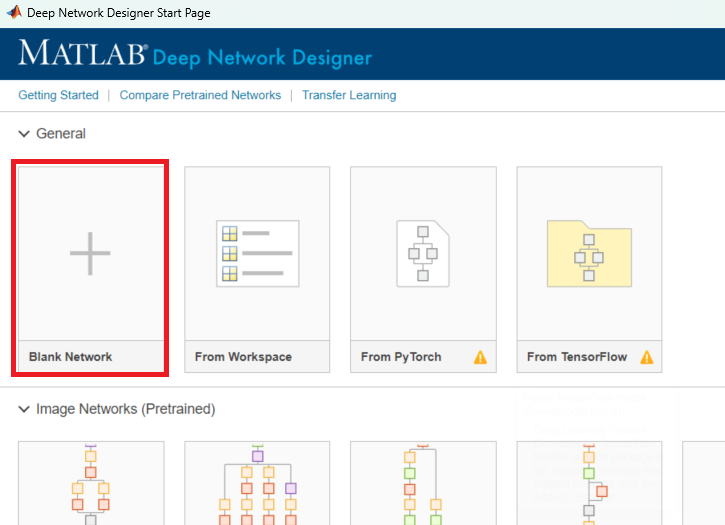

**ステップ 2: ネットワークを最初から作成する **

[デザイナー] タブで、必要なレイヤーをドラッグ アンド ドロップして必要な値を設定することで、以下のアーキテクチャを作成します。 

入力信号が 6 つあるため、input size =  6 をシーケンスに指定します。出力サイズが 128 (デフォルト) のbidirectional LSTM layerを指定し、シーケンスの最後の要素を分類用に出力します。 このコマンドは、双方向 LSTM レイヤーに、入力時系列を 128 個の特徴にマッピングするように指示してから、fully connected layerのための出力を準備します。最後に、サイズ 6 のfully connected layer、続けて、softmax layerを追加して、6 つのクラスを指定します。 

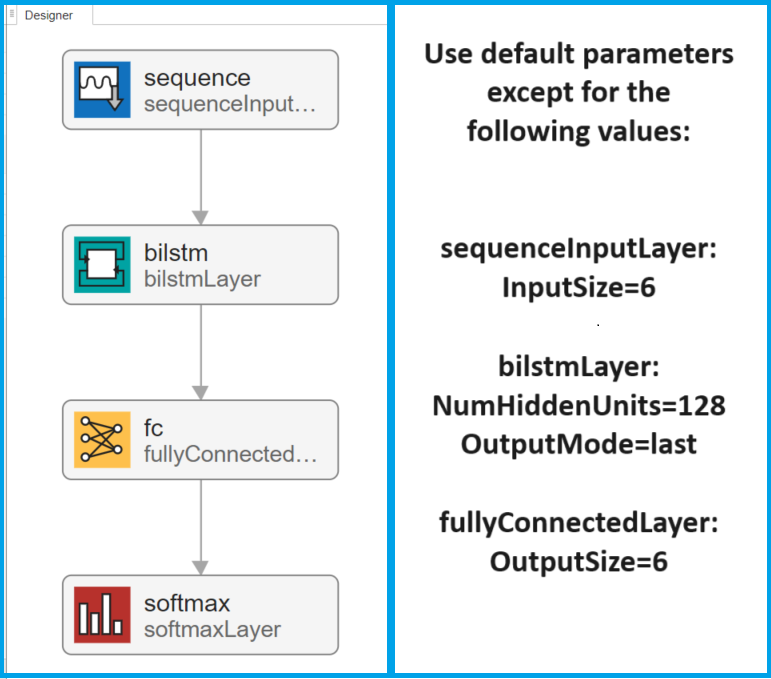

ネットワークを作成したら、エラーや警告がないかを確認するために解析（Analyze）を行うことができます。ネットワークに満足できたら、トレーニング用にエクスポート（Export）することが可能です。なお、ディープ ネットワーク デザイナー はネットワークをエクスポートするだけでなく、そのネットワークを作成するためのコード生成もできます。

ここでは、エクスポートをクリックし、ネットワークに"net_1"の名前でエクスポートしましょう。

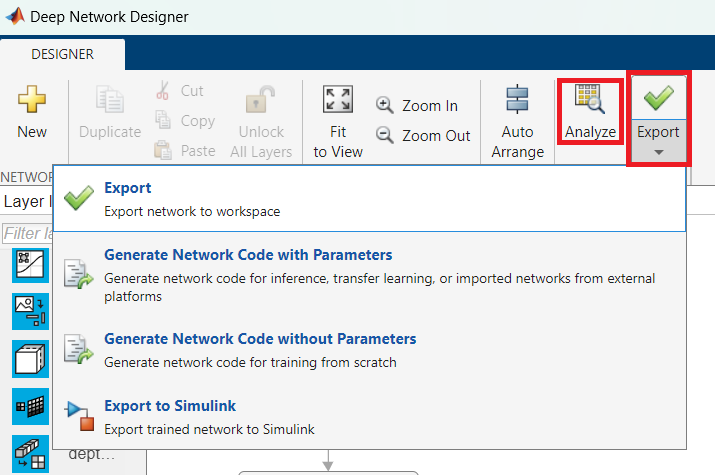

**ステップ 3: トレーニングデータをインポートする**

"データの前処理"セクションでは、トレーニング用およびテスト用のデータセットのインポート方法を確認しました。設計したニューラルネットワークの学習には、トレーニングデータセットを使用します。

※この例ではシンプルさを保つために、検証用データセットは使用していません。ただし、ネットワークの汎化能力を高め（過学習を防ぐ）ためには、検証用データセットの使用を強く推奨します。オリジナルのトレーニングデータセットを、トレーニング用と検証用の2つのサブセットに分割するには、[cvpartition](https://uk.mathworks.com/help/stats/cvpartition.html) を使用できます。

**ステップ 4: トレーニングのオプションの設定をする**

次に、このネットワークの学習オプションを設定し、以下のオプション（ハイパーパラメータ）を選択します。

- Solver: 'adam'

- MiniBatchSize: 128

- InitialLearnRate: 0.03

- MaxEpochs: 20

- LearnRateSchedule: 'piecewise'

- LearnRateDropFactor: 0.2

- LearnRateDropPeriod: 5

options = trainingOptions('adam', ...
     MaxEpochs = 20, ...
     InitialLearnRate=0.03,...
     MiniBatchSize=128, ...
     LearnRateSchedule= 'piecewise', ...
     LearnRateDropFactor=0.2, ...
     LearnRateDropPeriod=5, ...
     Plots = 'training-progress', ... 
     Metrics='accuracy', ...
     Verbose = false);

**ステップ 5: ネットワークを学習する **

net = trainnet(fullDS_train, net_1, "crossentropy", options)

上記のコマンドを実行してネットワークのトレーニングを開始します。GPUを使用すれば、トレーニングには約1.5分ほどかかるはずです。トレーニングの様子をプロットすると以下のような形になるはずです:

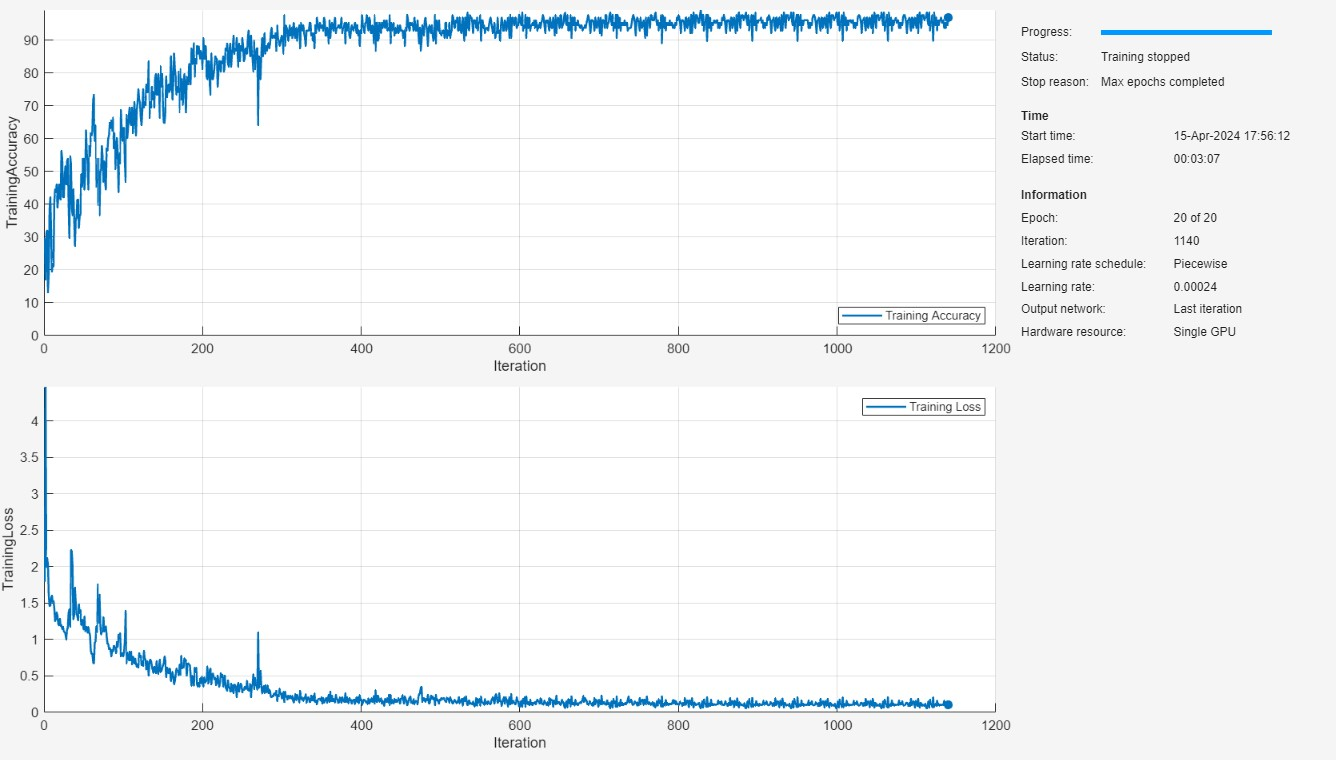

**ステップ 6: ハイパーパラメータを調整する**

注：[Experiment Manager アプリ](https://uk.mathworks.com/help/deeplearning/ref/experimentmanager-app.html)を使ってハイパーパラメータを調整することができます（少し高度です）。コードを生成することもできるので、毎回手動で行う必要はありません。また、学習したモデルをSimulinkで使用することもできます。

## モデルを評価する

ここまでの操作を行うことで、未知のデータ ( `fullDS_test` ) で精度を評価できます。 

テストデータのラベルがあるため、予測を実際のラベルと比較して、テスト精度を計算できます。 

classNames = unique(trainActivity);

y_pred = minibatchpredict(net,fullDS_test);
y_pred = scores2label(y_pred,classNames);

accuracy_test = sum(y_pred == testActivity)/numel(testActivity)*100

また、 [混同行列](https://uk.mathworks.com/help/stats/confusionchart.html) をプロットして結果を視覚化し、ネットワークのどこで問題が発生したかを確認することもできます。 

figure
ccLSTM = confusionchart(testActivity,y_pred);
ccLSTM.Title = 'Confusion Chart';
ccLSTM.ColumnSummary = 'column-normalized';
ccLSTM.RowSummary = 'row-normalized';

可視化してみると、このネットワークは主に歩行が関係する行動 (Walking、Walking upstairs、Walking Downstairs) の判別に苦労しています。これは、他のセンサーからの測定が必要であることを示している可能性があります。 

## まとめと次のステップ

この例では、スマートフォンから取得した人間の行動データを分類するディープラーニングモデルを構築しました。生データを使用し、基本モデルをトレーニングして、未知のデータでのパフォーマンスを評価しました。 

明らかに、この問題は十分に解決されておらず、最高のテスト精度はまだ 80%程度です。 

テスト精度を向上させるために試すことができる追加のステップをいくつか示します。  

- センサーデータの追加: 他のデータの測定値により、モデルがさまざまな歩行アクティビティを区別しやすくなる可能性があります。 

- クラスのバランス調整: 各クラスの観測数が異なることに気付いたかもしれません。 Layingの観測数が最も多く、Walking downstairsの観測数が最も少ない)。オーバーサンプリングやアンダーサンプリングなどの手法を使用して、クラスのバランスを調整します。 

- ネットワーク アーキテクチャの改善: この例では、LSTM モデルを使用しました。別のモデル (複数の LSTM レイヤーを持つ「より深い」モデルなど) を使用すると、精度も向上する可能性があります。ただし、これにはおそらくより多くの計算能力が必要になります。 

- ハイパーパラメータの調整: [Experiment Manager アプリ](https://www.mathworks.com/help/deeplearning/ug/exp-mgr-classification-example.html) を使用して、すべてのハイパーパラメータを追跡できます。または、[実験マネージャー アプリ内](https://jp.mathworks.com/help/releases/R2025a/deeplearning/ug/custom-training-experiment-using-bayesian-optimization.html) または [プログラム](https://www.mathworks.com/help/deeplearning/ug/deep-learning-using-bayesian-optimization.html#d123e28534) でベイズ最適化を実行して、最適なハイパーパラメータを見つけることもできます。 

*Copyright 2024, The MathWorks, Inc.*